# Discretization on a 2D spherical shell

clc, close all, clear
set_demo_defaults;

Next we extend the discretization to a 2D spherical shell. The divergence and grdient operators are given by

Gradient:       $\nabla h=\frac{1}{R}\frac{\partial h}{\partial \theta}\hat{\mathbf{\theta}}+\frac{1}{R\sin\theta}\frac{\partial h}{\partial \varphi}\hat{\mathbf{\varphi}}$

Divergence: $\nabla\cdot\mathbf{q}=\frac{1}{R\sin\theta} \frac{\partial}{\partial \theta}\left(\sin\theta q_\theta\right) + \frac{1}{R\sin\theta} \frac{\partial q_\varphi}{\partial\varphi}$

where $R$ is the radius of the spherical shell, $\theta$ is the polar angle and $\varphi$ is the azimuthal angle. Since we want to be able to reduce to the $\theta$ only case with azimuthal symmetry, we choose `x` as the $\theta$ direction and `y` as the $\varphi$ direction. Hence the Gx and Dy operators are constructed similar to the 1D spherical shell case and are simply extended to two dimensions by using the Kronecker product.

theta_p = deg2rad(5);
theta_b = pi-acos(1/3);
theta_ana = linspace(theta_p,theta_b,100);
Grid.xmin = 0; Grid.xmax = theta_b; Grid.Nx = 25;
Grid.ymin = 0; Grid.ymax = 2*pi; Grid.Ny = 50;
Grid = build_grid(Grid);
Grid.R_shell = 1;

## 1. 2D operators on spherical shell

### 1.1 Dx and Gx (polar angle)

First we generate the corresponding 1D matrices in x in linear cartesian coordinates.

Nx = Grid.Nx; Ny = Grid.Ny;
Dx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[0 1],Nx,Nx+1);  % 1D div-matrix in x-dir
Gx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[-1 0],Nx+1,Nx); % 1D grad-matrix in x-dir

Then we modify them according to the form of the differential operators on a spherical cap and use Kronecker products to extend them to 2D operators.

Sin_f = spdiags(sin(Grid.xf),0,Nx+1,Nx+1);
R_sin_c_inv = spdiags(1./(Grid.R_shell*sin(Grid.xc)),0,Nx,Nx);
Dx = R_sin_c_inv*Dx*Sin_f;  % 1D polar D
Gx = Gx/Grid.R_shell;       % 1D polar G
Dx = kron(Dx,speye(Ny));    % 2D polar D
Gx = kron(Gx,speye(Ny));    % 2D polar G

### 1.2 Dy and Gy (azimuthal angle)

Note that both the azimutal gradient and the azimutal divergence are multiplied by the term $1/(R\sin\theta)$, as such the ahve a similar construction. First we generate the corresponding 1D matrizes in y in linear cartesian coordinates.

Dy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[0 1],Ny,Ny+1);  % 1D div-matrix in y-dir
Gy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[-1 0],Ny+1,Ny); % 1D grad-matrix in y-dir

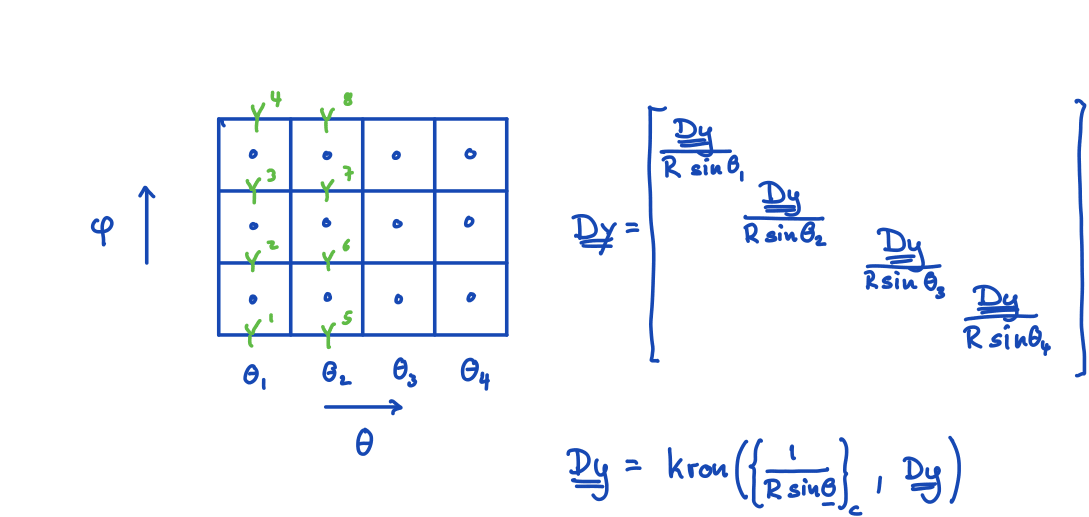

The figure above illustrates the construction of the `Dy` operator. This is slightly different from the construction of the `Dx` operator where the 1D `Dx` matrix is mutliplied before we take the Kronecker product with an identity. Here each block in the 2D `Dy` matrix is multiplied by a different value of $1/(R\sin\theta)$ according to the $\theta$ value of that column of grid cells. This can be achived by taking the Kronecker product between appropriate diagonal matrix and the 1D `Dy` as shown in the figure. First we build this diagonal matrix

R_sin_c_inv = spdiags(1./(Grid.R_shell*sin(Grid.xc)),0,Nx,Nx);

which now takes the place of `Ix` in the construction of both the 2D `Dy` and `Gy` operators

Dy = kron(R_sin_c_inv,Dy);    % 2D azimutal D
Gy = kron(R_sin_c_inv,Gy);    % 2D azimutal G

### 1.3 Assembly of the full 2D matrices

Once Dx, Dy, Gx and Gy are known we assemble the full 2D matrices as before

D = [Dx,Dy];
G = [Gx;Gy];
dof_f_bnd = [Grid.dof_f_xmin; Grid.dof_f_xmax;...
             Grid.dof_f_ymin; Grid.dof_f_ymax];
G(dof_f_bnd,:) = 0;
I = speye(Grid.N);

and impose the natural boundary conditions. All of this will be integrated into the `build_ops.m` function and can be chosen with a keyword.

## 2. First solutions on a spherical shall

### 2.1 Solving confined aquifer with precipitation on a 2D spherical shell

Now we are ready to try ans solve for the head in a confined aquifer with precipitation on a 2D spherical shell. As discussed previously the dimensionless governing equations are given by

PDE: $-\nabla\cdot\nabla h' = 1$on $(\theta,\,\varphi)\in\left[0,\,\theta_b\right]\times\left[0,\,2\pi\right]$

BC: $h'(\theta_b,\varphi) = 0$

Due to azimuthal symmetry the solution only depends on $\theta$ and the analytic solution is given by

$h' = \log\left(\frac{\cos\theta+1}{\cos\theta_b+1}\right)$ and $q' = \frac{1-\cos\theta}{\sin\theta} = \csc\theta - \cot\theta$.

theta_ana =  linspace(0,theta_b,1e2);
hD_ana = @(theta,theta_p) log(sin(theta)/sin(theta_b)) + cos(theta_p)*log( (csc(theta)+cot(theta) )/( csc(theta_b)+cot(theta_b) ));
qD_ana = @(theta,theta_p) cos(theta_p)*csc(theta) - cot(theta);

Given that the details of the coordinate system and the dimensionality are hiden in the operators, we have simply

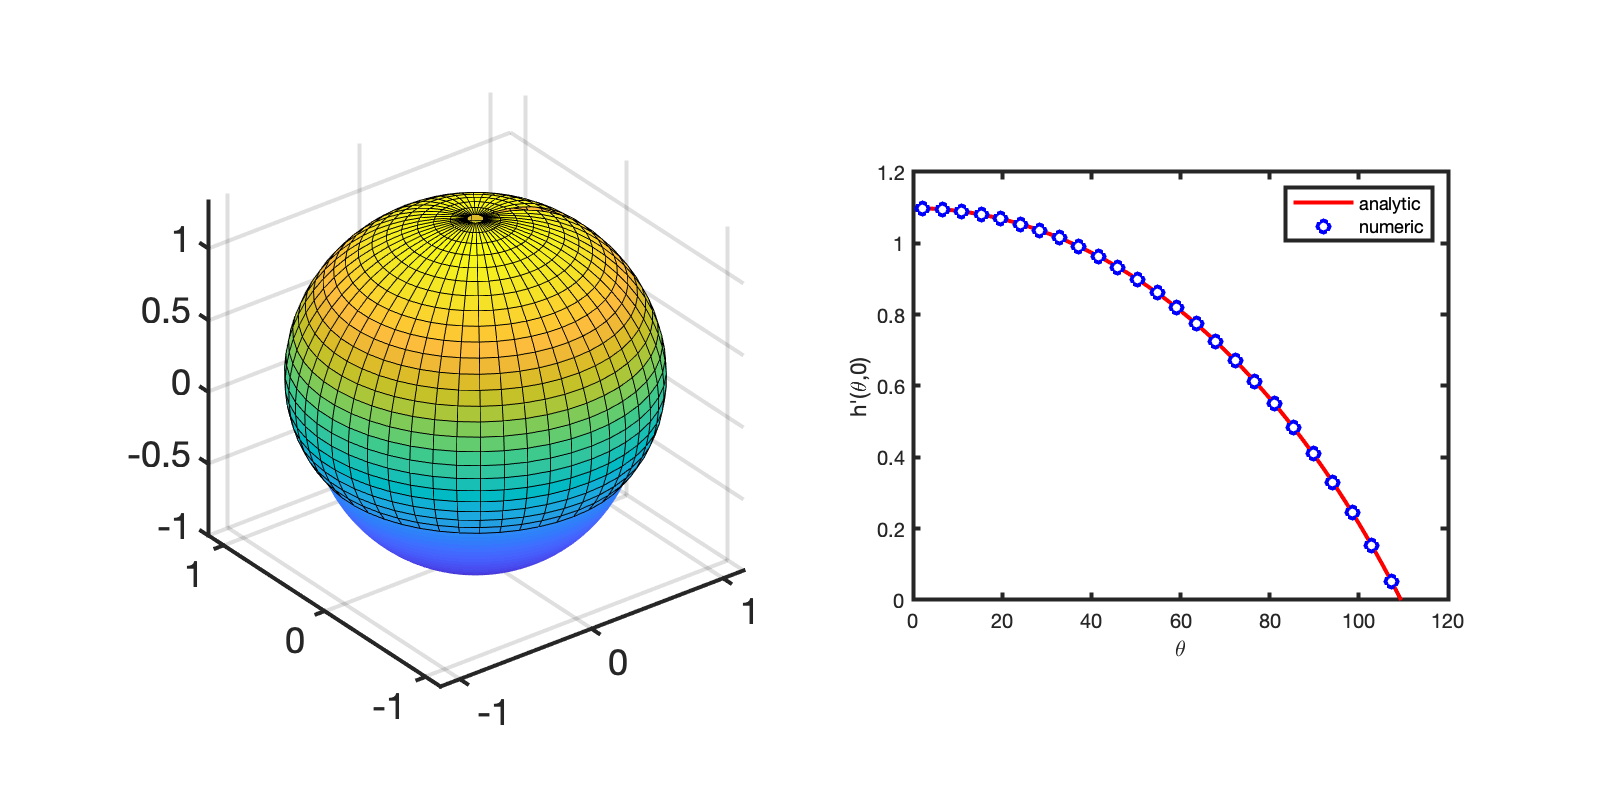

L = -D*G;
fs = ones(Grid.N,1);

%% Boundary conditions
BC.dof_dir = [Grid.dof_xmax];
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = hD_ana(Grid.xc(end),theta_p)*ones(Grid.Ny,1);
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);

hD = solve_lbvp(L,fs+fn,B,BC.g,N);

figure('position',[10 10 800 400])
subplot 121
plot_spherical_shell(hD,.3,Grid)
subplot 122
plot(rad2deg(theta_ana),hD_ana(theta_ana,0),'r-'), hold on
plot(rad2deg(Grid.xc),hD(Grid.dof_ymin),'bo','markerfacecolor','w','markersize',6)
pbaspect([1 .8 1])
xlabel('\theta')
ylabel('h''(\theta,0)')
legend('analytic','numeric')

This shows that we recover the solution with azimuthal symmetry. Note that we do not have a problem at th pole although our domain goes all the way to $\theta=0$. this is because we only need $\theta$ at the cell centers in the $1/(R\sin\theta)$ terms!

### 2.2 Solution with localized precipitation

Consider the same problem with an asymmetric source term that is unit in the sector $(\theta,\,\varphi)\in\left[0,\,\pi/4\right]\times\left[0,\,\pi/4\right]$ and zero elsewhere

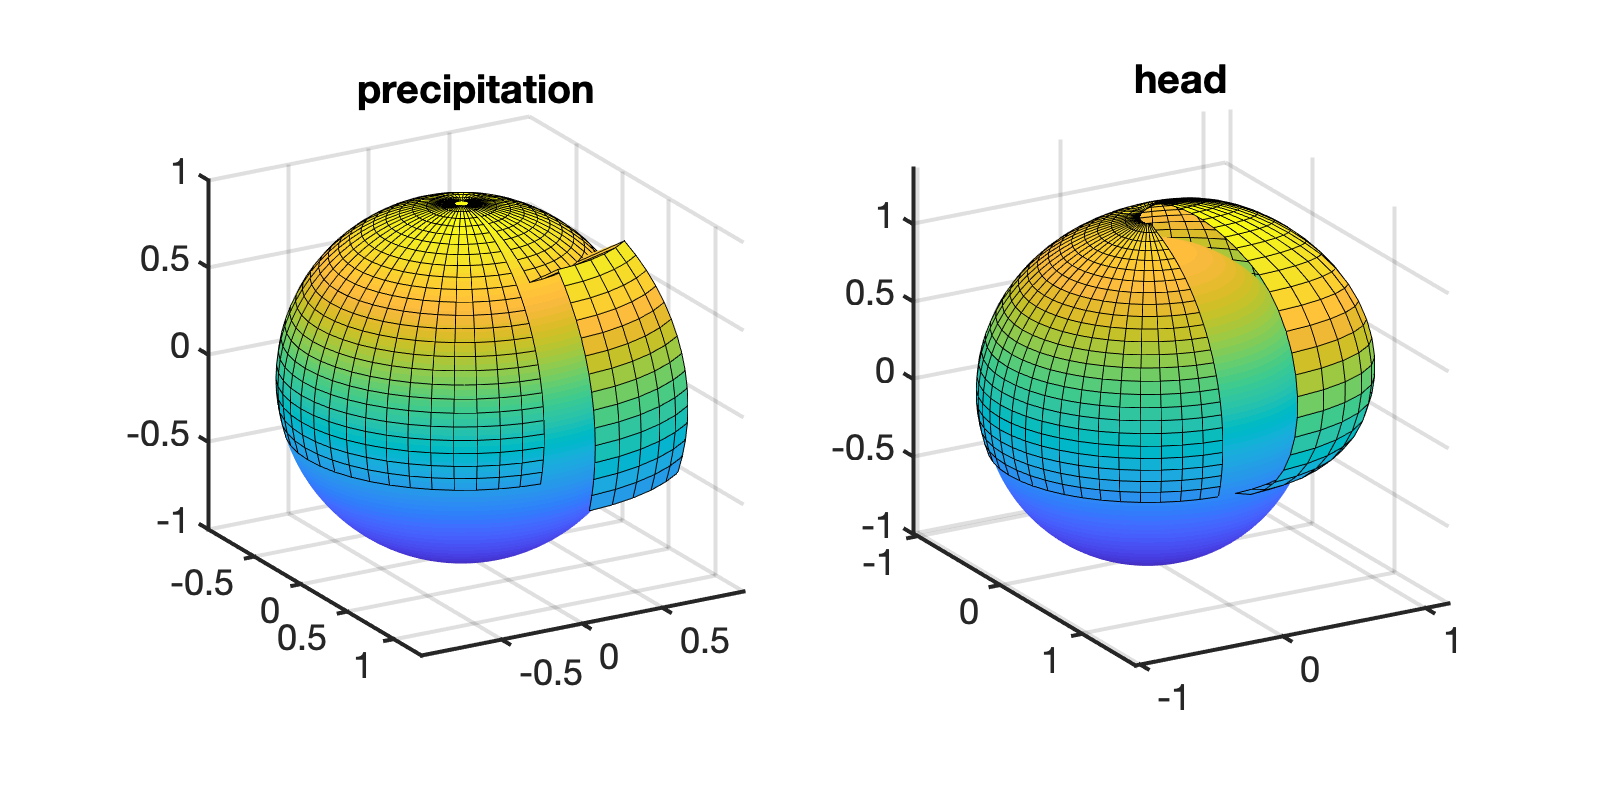

[Theta,Phi] = meshgrid(Grid.xc,Grid.yc);
fs = 10*ones(Grid.N,1);
fs(Phi(:)>pi/4) = 0;
fs(Theta(:)<pi/4) = 0;
hD = solve_lbvp(L,fs+fn,B,BC.g,N);

figure('position',[10 10 800 400])
subplot 121
plot_spherical_shell(fs,.03,Grid)
title 'precipitation'
view(60,20)

subplot 122
plot_spherical_shell(hD,.3,Grid)
title 'head'
view(60,20)

The head has a discontinuity at $\varphi=0=2\pi$, because the azimutal gradient has natural boundary conditions built in. Instead, we need periodic boundary conditions in the azimutal direction for calculations on a spherical shell.

## 3. Periodic boundary conditions

The periodic nature of the solution above is interupted by the natural boundary conditions of the gradient. Hence we only need to modify the discrete gradient in the azimuthal direction to resolve the problem. The divergence operator does not need to be changed.

Consider the periodic function, $g(x) = e^{\cos(2\pi x)}$, that does not satify the natural BC's,

xa = linspace(0,3,3e2);
g = @(x) exp(sin(2*pi*x));
dgdx = @(x) exp(sin(2*pi*x)).*cos(2*pi*x)*2*pi; 
d2gdx2 = @(x) 2*pi^2*exp(sin(2*pi*x)).*(-2*sin(2*pi*x)+cos(4*pi*x)+1);

If we use the standard discrete gradient to compute the derivative we have an error on the boundary

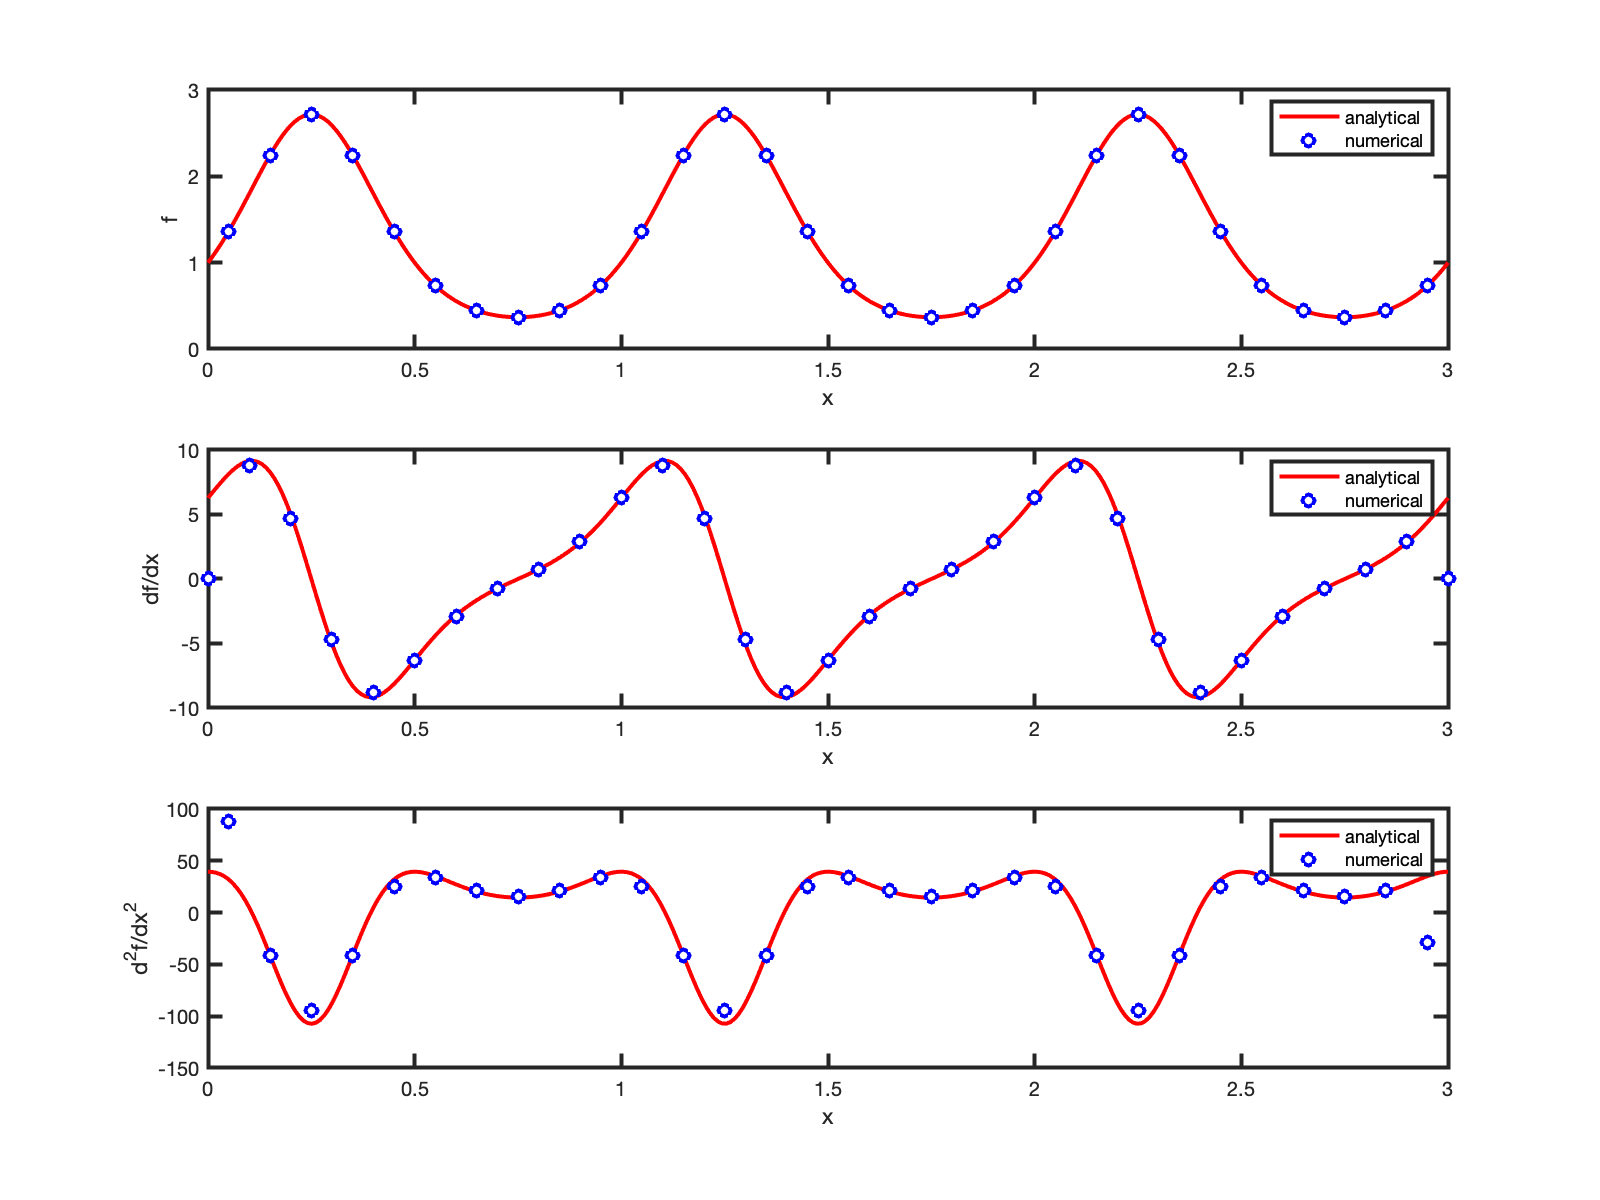

clear Grid
Grid.xmin = 0; Grid.xmax = 3; Grid.Nx = 30;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid); L = D*G;

figure('position',[10 10 800 600])
title 'Natural BC''s'
subplot 311
plot(xa,g(xa),'r',Grid.xc,g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'f'
legend('analytical','numerical')

subplot 312
plot(xa,dgdx(xa),'r',Grid.xf,G*g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'df/dx'
legend('analytical','numerical')

subplot 313
plot(xa,d2gdx2(xa),'r',Grid.xc,L*g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'd^2f/dx^2'
legend('analytical','numerical')

### 3.1 Periodic discrete gradient

To construct a gradient with periodic boundary conditions consider the following simple 1D grid

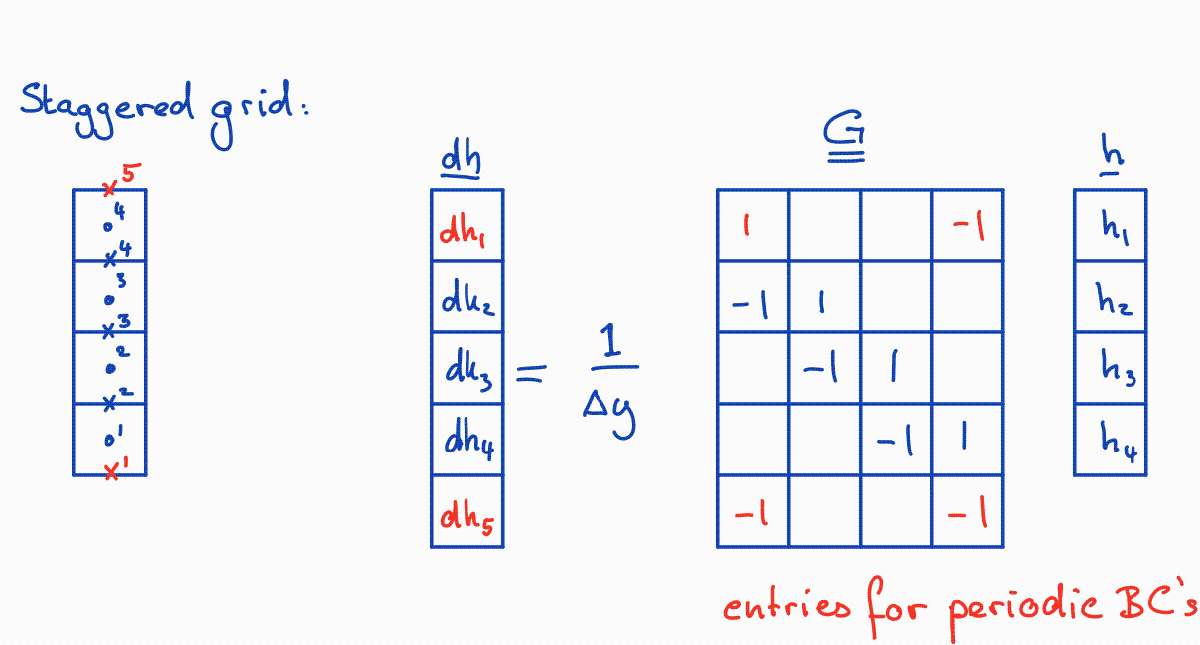

To implement periodic boundary conditions we use information from the first and last cell to compute the identical fluxes on the first and last face, as shown in the figure. This can be implemented easily by adding the additional entried the the gradient with the natural boundary conditions as follows.

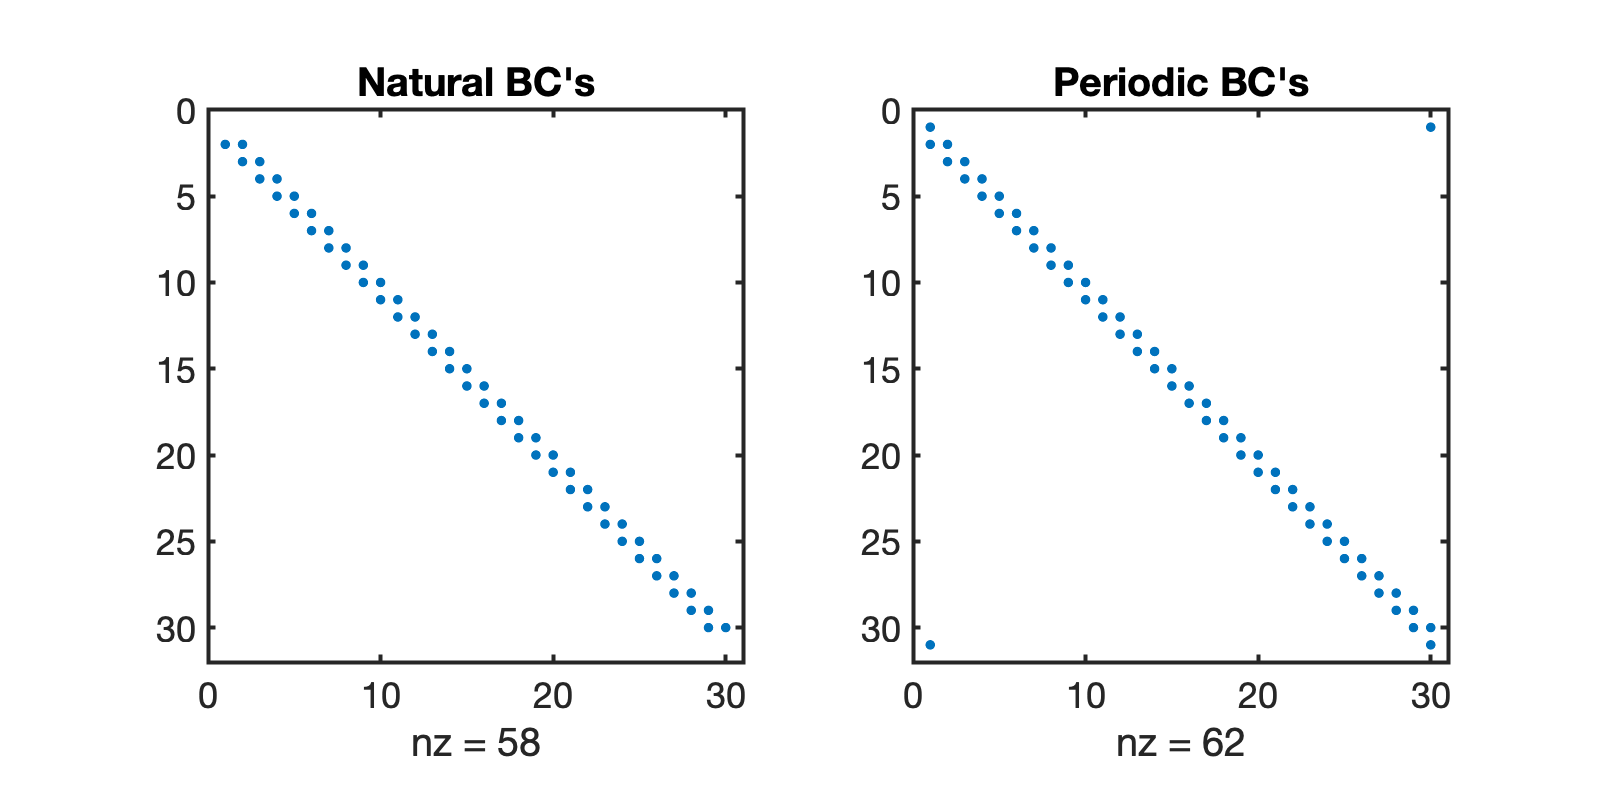

figure('position',[10 10 800 400])
subplot 121
spy(G)
title 'Natural BC''s'

%% Additional entries for periodic BC's
G(1,1)               =  1/Grid.dx;
G(1,Grid.Nx)         = -1/Grid.dx;
G(Grid.Nx+1,1)       =  1/Grid.dx;
G(Grid.Nx+1,Grid.Nx) = -1/Grid.dx;

subplot 122
spy(G)
title 'Periodic BC''s'

With this simple modification the discrete gradient approximates the periodic function appropriately.

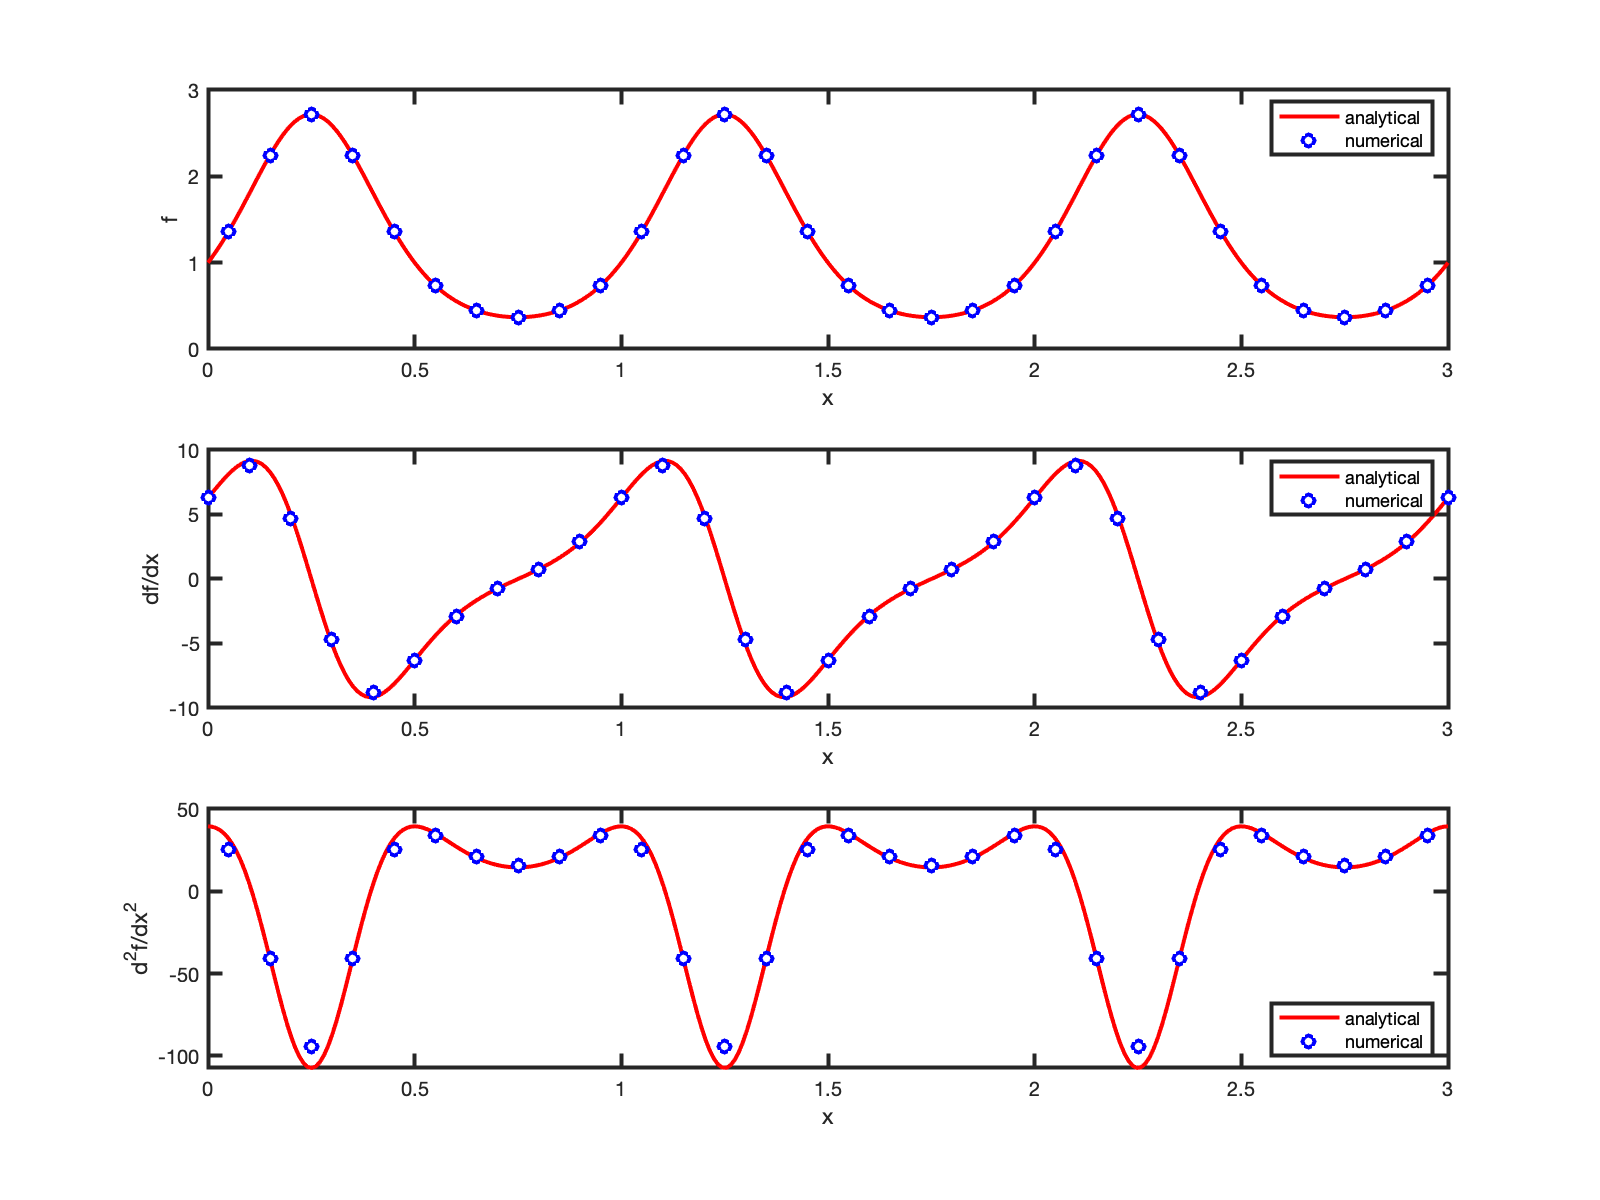

figure('position',[10 10 800 600])
title 'Periodic BC''s'
subplot 311
plot(xa,g(xa),'r',Grid.xc,g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'f'
legend('analytical','numerical')

subplot 312
plot(xa,dgdx(xa),'r',Grid.xf,G*g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'df/dx'
legend('analytical','numerical')

subplot 313
plot(xa,d2gdx2(xa),'r',Grid.xc,D*G*g(Grid.xc),'bo','markerfacecolor','w','markersize',6)
xlabel 'x'
ylabel 'd^2f/dx^2'
legend('analytical','numerical','location','southeast')

### 3.2 Periodic spherical shell operators

The periodic boundary contition in the azimuthal direction can be incorporated in the spherical shell operators, simply by modifying the 1D `Dy` operator! This a benefit of the modular construction of our discretization.

First we need to regenerate the finer grid.

Grid.xmin = 0; Grid.xmax = theta_b; Grid.Nx = 25;
Grid.ymin = 0; Grid.ymax = 2*pi; Grid.Ny = 50;
Grid = build_grid(Grid);
Grid.R_shell = 1;

Then we copy the construction of the spherical shell operators from above.

 The x-operators in the $\theta$-direction are **not modified** at all.

Nx = Grid.Nx; Ny = Grid.Ny;
Dx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[0 1],Nx,Nx+1);  % 1D div-matrix in x-dir
Gx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[-1 0],Nx+1,Nx); % 1D grad-matrix in x-dir
Sin_f = spdiags(sin(Grid.xf),0,Nx+1,Nx+1);
R_sin_c_inv = spdiags(1./(Grid.R_shell*sin(Grid.xc)),0,Nx,Nx);
Dx = R_sin_c_inv*Dx*Sin_f;  % 1D polar D
Gx = Gx/Grid.R_shell;       % 1D polar G
Dx = kron(Dx,speye(Ny));    % 2D polar D
Gx = kron(Gx,speye(Ny));    % 2D polar G

The Gy operator is modified to approximate periodic BC's by adding the following line adding the off-diagonal entries in the corners. Note the diagonal entries for the periodic BC's are added by the basic construction from sparse diagonals and are usually zeroed out.

Dy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[0 1],Ny,Ny+1);  % 1D div-matrix in y-dir
Gy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[-1 0],Ny+1,Ny); % 1D grad-matrix in y-dir
Gy(1,Ny) = -1/Grid.dy; Gy(Ny+1,1) = 1/Grid.dy;                 % periodic BC's in y-dir

The modification for spherical geometry and the extension to 2D follow as before.

R_sin_c_inv = spdiags(1./(Grid.R_shell*sin(Grid.xc)),0,Nx,Nx);
Dy = kron(R_sin_c_inv,Dy);    % 2D azimutal D
Gy = kron(R_sin_c_inv,Gy);    % 2D azimutal G

The full matrices are then assemble for the four block matrices as always

D = [Dx,Dy];
G = [Gx;Gy];
I = speye(Grid.N);
L = -D*G;

Finally, we need to be careful not to zero-out the periodic BC's when enforcing the Natural boundary conditions on the other boundaries. As such we only cancel the entries on the xmin and xmax boundaries.

dof_f_bnd = [Grid.dof_f_xmin; Grid.dof_f_xmax]; % Natural BC's x-dir
G(dof_f_bnd,:) = 0;

Now we can re-solve the problem wiith the localized precipitation to see if the periodic nature of the solution has been achieved

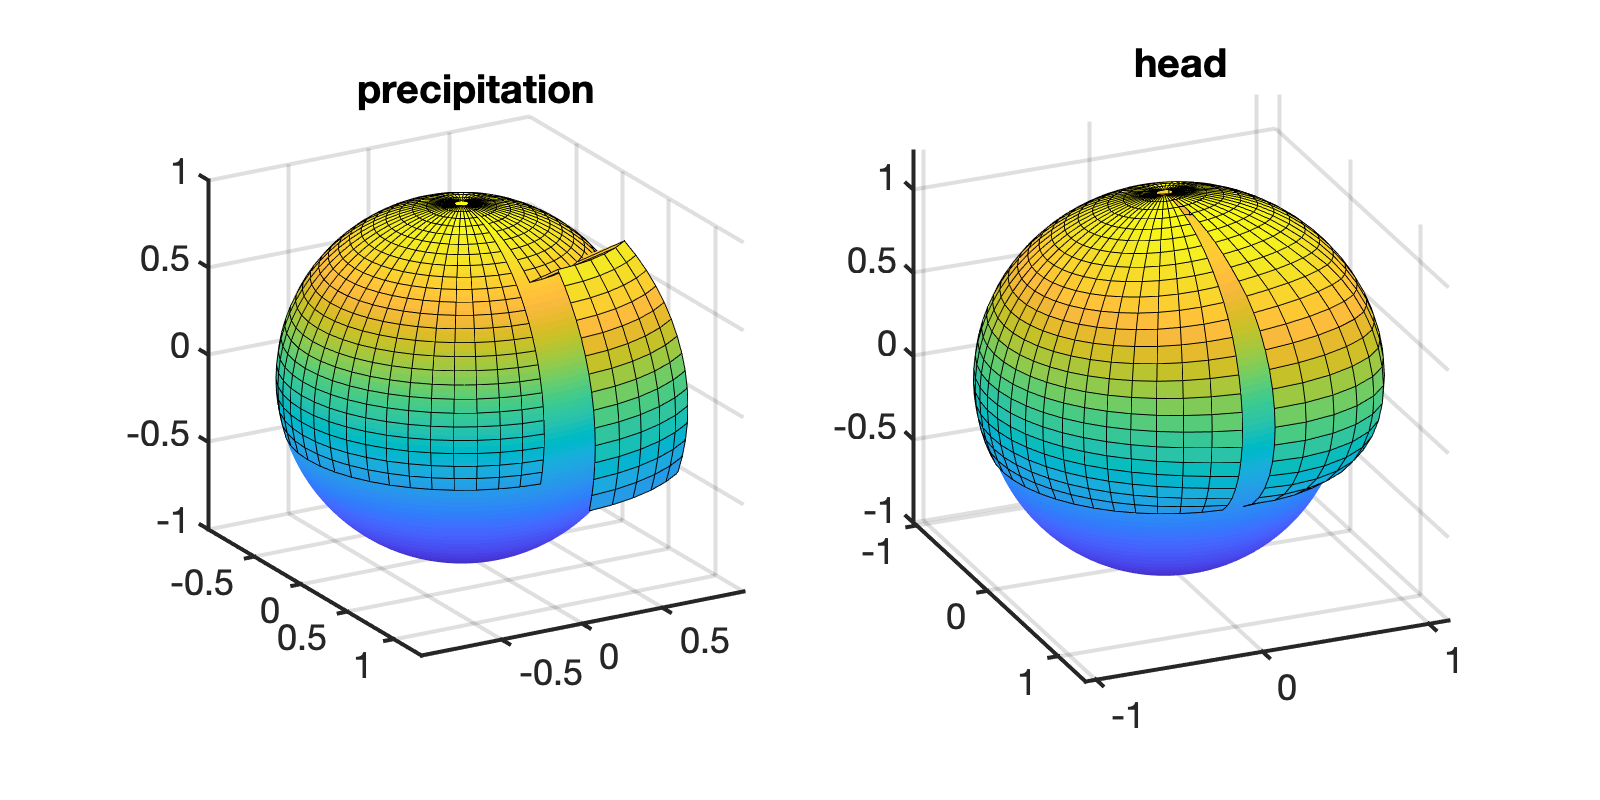

%% Boundary conditions
BC.dof_dir = [Grid.dof_xmax];
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = hD_ana(Grid.xc(end),theta_p)*ones(Grid.Ny,1);
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);

[Theta,Phi] = meshgrid(Grid.xc,Grid.yc);
fs = 10*ones(Grid.N,1);
fs(Phi(:)>pi/4) = 0;
fs(Theta(:)<pi/4) = 0;
hD = solve_lbvp(L,fs+fn,B,BC.g,N);

figure('position',[10 10 800 400])
subplot 121
plot_spherical_shell(fs,.03,Grid)
title 'precipitation'
view(60,20)

subplot 122
plot_spherical_shell(hD,.3,Grid)
title 'head'
view(60,20)

You're welcome!

## Auxillary functions

#### plot_spherical_shell()

function [] = plot_spherical_shell(hD,scale,Grid)
% Plot sphere
[Theta_s,Phi_s] = meshgrid(linspace(0,pi,100),linspace(0,2*pi,100));
R = 1;
Xs = R*sin(Theta_s).*cos(Phi_s);
Ys = R*sin(Theta_s).*sin(Phi_s);
Zs = R*cos(Theta_s);

% solution
[Theta,Phi] = meshgrid(Grid.xc,Grid.yc);
Hd = reshape(hD,Grid.Ny,Grid.Nx);
Xh = (R+scale*Hd).*sin(Theta).*cos(Phi);
Yh = (R+scale*Hd).*sin(Theta).*sin(Phi);
Zh = (R+scale*Hd).*cos(Theta);

surf(Xs,Ys,Zs), hold on
shading interp
surf(Xh,Yh,Zh)
axis equal
end